clear; clc; close all;

% Load dataset
data = readtable('C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\continuous dataset.csv');
% Extract features and target variable
feature_names = {'T2M_toc', 'QV2M_toc', 'W2M_toc', 'TQL_toc', 'T2M_san', 'QV2M_san', 'W2M_san', 'TQL_san', 'T2M_dav', 'QV2M_dav', 'W2M_dav', 'TQL_dav'};
X = table2array(data(:, feature_names)); % Features
y = data.nat_demand; % Target variable (Load Demand)

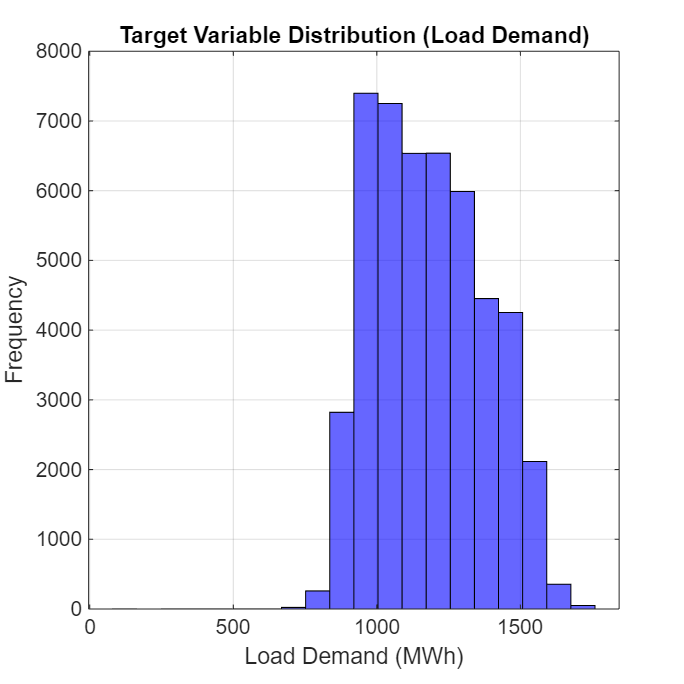

% Create figure with increased height for better spacing
figure('Position', [100, 100, 800, 800]); 

% Target Variable Distribution (Load Demand)
subplot(1,1,1); 
histogram(y, 20, 'FaceColor', 'b');
title('Target Variable Distribution (Load Demand)');
xlabel('Load Demand (MWh)'); ylabel('Frequency'); grid on;


% Load dataset
data = readtable('C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\continuous dataset.csv');

% Define cities and their feature prefixes
cities = {'toc', 'san', 'dav'};
city_features = {
    {'T2M_toc', 'QV2M_toc', 'W2M_toc', 'TQL_toc'},
    {'T2M_san', 'QV2M_san', 'W2M_san', 'TQL_san'},
    {'T2M_dav', 'QV2M_dav', 'W2M_dav', 'TQL_dav'}
};


model_folder = 'C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\city_model_saves\';
if ~exist(model_folder, 'dir')
    mkdir(model_folder);
end


for c = 1:length(cities)
    city = cities{c};
    features = city_features{c};

   
    X = table2array(data(:, features));
    y = data.nat_demand;  

    % Create lag features
    num_lags = 24;
    X_lagged = [];
    for i = 1:num_lags
        X_lagged = [X_lagged, circshift(y, i)];
    end
    X = X(num_lags+1:end, :);
    X_lagged = X_lagged(num_lags+1:end, :);
    y = y(num_lags+1:end);
    X = [X, X_lagged];

    % Train/Test Split
    cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
    X_train = X(training(cv), :); y_train = y(training(cv));
    X_test = X(test(cv), :); y_test = y(test(cv));

    % Normalize
    mu_X = mean(X_train); sigma_X = std(X_train);
    X_train_scaled = (X_train - mu_X) ./ sigma_X;
    X_test_scaled = (X_test - mu_X) ./ sigma_X;

    mu_y = mean(y_train); sigma_y = std(y_train);
    y_train_scaled = (y_train - mu_y) ./ sigma_y;

    % Train SVM 
    svm_model = fitrsvm(X_train_scaled, y_train_scaled, ...
        'KernelFunction', 'rbf', ...
        'OptimizeHyperparameters', 'auto', ...
        'HyperparameterOptimizationOptions', struct('ShowPlots', false, ...
            'Verbose', 1, 'MaxObjectiveEvaluations', 30));

    %Train ANN 
    ann_net = feedforwardnet([50 25]);
    ann_net.trainParam.showWindow = false;
    ann_net = train(ann_net, X_train_scaled', y_train_scaled');

    %  Save Models 
    svm_path = fullfile(model_folder, [city '_svm_model.mat']);
    ann_path = fullfile(model_folder, [city '_ann_model.mat']);

    save(svm_path, 'svm_model', 'mu_X', 'sigma_X', 'mu_y', 'sigma_y');
    save(ann_path, 'ann_net', 'mu_X', 'sigma_X', 'mu_y', 'sigma_y');

    fprintf(' Models saved for city: %s\n', city);
end

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.039774 |      69.157 |    0.039774 |    0.039774 |       216.25 |       931.98 |    0.0013204 |         true |
|    2 | Accept |     0.69315 |      2.3551 |    0.039774 |    0.077844 |      0.12389 |       0.7068 |       4.6139 |         true |
|    3 | Accept |     0.69589 |      67.774 |    0.039774 |    0.040184 |     0.084514 |     0.021197 |     0.091478 |        false |
|    4 | Best   |    0.030236 |      53.049 |    0.030236 |   

 Models saved for city: toc


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.69566 |      65.114 |     0.69566 |     0.69566 |    0.0082295 |      0.15611 |     0.018453 |        false |
|    2 | Best   |     0.69315 |       1.878 |     0.69315 |      0.6944 |    0.0077398 |       14.528 |       87.676 |         true |
|    3 | Accept |     0.69315 |      1.7378 |     0.69315 |     0.69398 |       112.86 |     0.038663 |       24.254 |        false |
|    4 | Best   |    0.017343 |      31.295 |    0.017343 |   

 Models saved for city: san


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.063637 |      9.5356 |    0.063637 |    0.063637 |        867.3 |       2.8103 |      0.55344 |         true |
|    2 | Accept |     0.69315 |      1.5861 |    0.063637 |      0.1138 |     0.011803 |     0.099298 |       113.67 |        false |
|    3 | Accept |     0.10482 |      52.186 |    0.063637 |    0.085535 |     0.018337 |        30.56 |    0.0031856 |         true |
|    4 | Accept |     0.69315 |      1.7897 |    0.063637 |   

 Models saved for city: dav


clear; clc; close all;


data = readtable('C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\continuous dataset.csv');

cities = {'toc', 'san', 'dav'};
city_features = {
    {'T2M_toc', 'QV2M_toc', 'W2M_toc', 'TQL_toc'},
    {'T2M_san', 'QV2M_san', 'W2M_san', 'TQL_san'},
    {'T2M_dav', 'QV2M_dav', 'W2M_dav', 'TQL_dav'}
};

% Model folder
model_folder = 'C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\city_model_saves\';

all_cities = {};
all_models = {};
mae_values = [];
rmse_values = [];
r2_values = [];

% Table to store results
results = table();

for c = 1:length(cities)
    city = cities{c};
    features = city_features{c};

    % Prepare Data
    X = table2array(data(:, features));
    y = data.nat_demand;  

    % Create lag features
    num_lags = 24;
    X_lagged = [];
    for i = 1:num_lags
        X_lagged = [X_lagged, circshift(y, i)];
    end
    X = X(num_lags+1:end, :);
    X_lagged = X_lagged(num_lags+1:end, :);
    y = y(num_lags+1:end);
    X = [X, X_lagged];

    % Train/Test Split
    cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
    X_train = X(training(cv), :); y_train = y(training(cv));
    X_test = X(test(cv), :); y_test = y(test(cv));

    % Load Models
    svm_path = fullfile(model_folder, [city '_svm_model.mat']);
    ann_path = fullfile(model_folder, [city '_ann_model.mat']);

    load(svm_path, 'svm_model', 'mu_X', 'sigma_X', 'mu_y', 'sigma_y');
    load(ann_path, 'ann_net');

    % Normalize test data
    X_test_scaled = (X_test - mu_X) ./ sigma_X;

    %  SVM Evaluation
    y_pred_svm_scaled = predict(svm_model, X_test_scaled);
    y_pred_svm = y_pred_svm_scaled * sigma_y + mu_y;

    MAE_svm = mean(abs(y_test - y_pred_svm));
    RMSE_svm = sqrt(mean((y_test - y_pred_svm).^2));
    R2_svm = 1 - sum((y_test - y_pred_svm).^2) / sum((y_test - mean(y_test)).^2);

    results = [results; {upper(city), 'SVM', MAE_svm, RMSE_svm, R2_svm}];

    % ANN Evaluation 
    y_pred_ann_scaled = ann_net(X_test_scaled')';
    y_pred_ann = y_pred_ann_scaled * sigma_y + mu_y;

    MAE_ann = mean(abs(y_test - y_pred_ann));
    RMSE_ann = sqrt(mean((y_test - y_pred_ann).^2));
    R2_ann = 1 - sum((y_test - y_pred_ann).^2) / sum((y_test - mean(y_test)).^2);

    results = [results; {upper(city), 'ANN', MAE_ann, RMSE_ann, R2_ann}];

    % Store metrics 
    all_cities = [all_cities; repmat({upper(city)}, 2, 1)];
    all_models = [all_models; {'SVM'; 'ANN'}];
    mae_values = [mae_values; MAE_svm; MAE_ann];
    rmse_values = [rmse_values; RMSE_svm; RMSE_ann];
    r2_values = [r2_values; R2_svm; R2_ann];

end


results.Properties.VariableNames = {'City', 'Model', 'MAE', 'RMSE', 'R2'};

disp(results);

     City       Model      MAE       RMSE       R2   
    _______    _______    ______    ______    _______

    {'TOC'}    {'SVM'}    13.487    19.489     0.9899
    {'TOC'}    {'ANN'}    13.699    19.052    0.99035
    {'SAN'}    {'SVM'}    13.967    20.387     0.9888
    {'SAN'}    {'ANN'}    13.127    20.028     0.9892
    {'DAV'}    {'SVM'}    12.977    20.462    0.98881
    {'DAV'}    {'ANN'}    13.546    20.744     0.9885



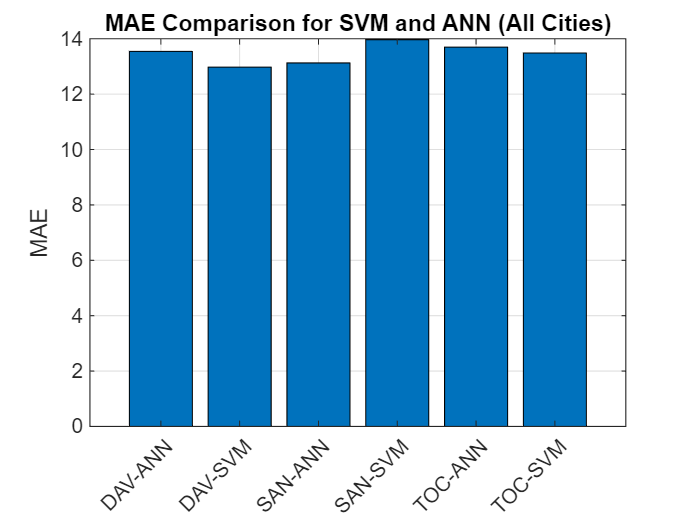


labels = strcat(upper(string(all_cities)), '-', string(all_models));

% MAE 
figure;
bar(categorical(labels), mae_values);
title('MAE Comparison for SVM and ANN (All Cities)');
ylabel('MAE');
xtickangle(45);
grid on;

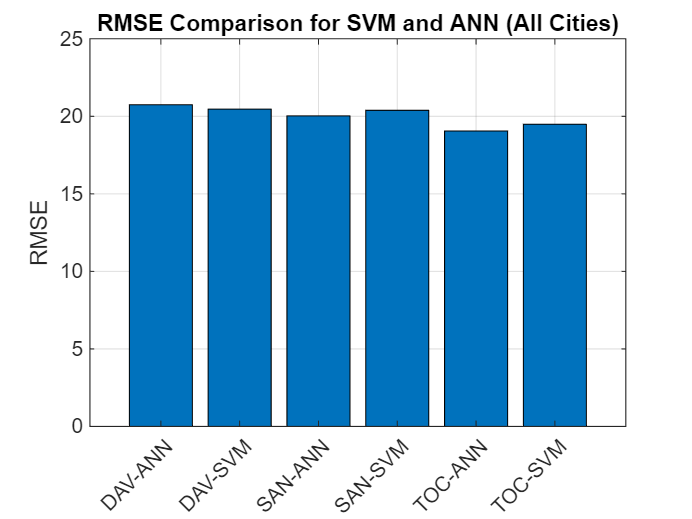


% RMSE Plot
figure;
bar(categorical(labels), rmse_values);
title('RMSE Comparison for SVM and ANN (All Cities)');
ylabel('RMSE');
xtickangle(45);
grid on;

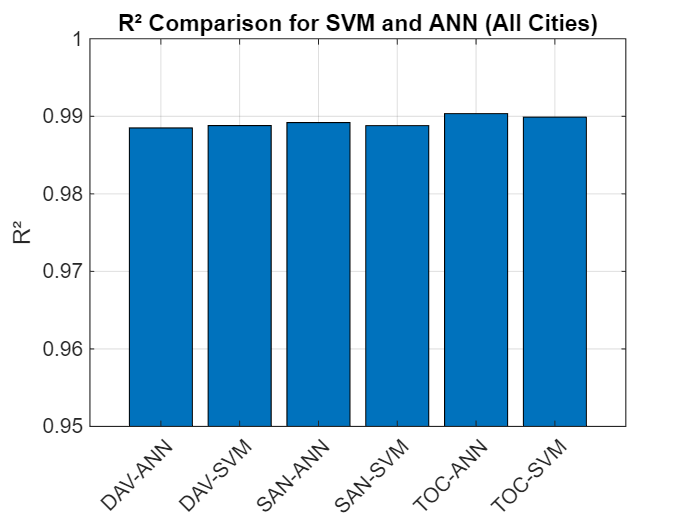


% R²
figure;
bar(categorical(labels), r2_values);
title('R² Comparison for SVM and ANN (All Cities)');
ylabel('R²');
ylim([0.95 1]);  
xtickangle(45);
grid on;


city = 'toc'; 
model_type = 'svm';  

model_path = fullfile(model_folder, [city '_' model_type '_model.mat']);
loaded = load(model_path);

if strcmp(model_type, 'svm')
    model = loaded.svm_model;
else
    model = loaded.ann_net;
end

mu_X = loaded.mu_X;
sigma_X = loaded.sigma_X;
mu_y = loaded.mu_y;
sigma_y = loaded.sigma_y;

% Normalize test data with training stats
X_test_scaled = (X_test - mu_X) ./ sigma_X;
% Get predictions
if strcmp(model_type, 'svm')
    y_pred_scaled = predict(model, X_test_scaled);
else
    y_pred_scaled = model(X_test_scaled')';
end

% Reverse normalization
y_pred = y_pred_scaled * sigma_y + mu_y;

% Actual values (original)
y_actual = y_test;

% Evaluation Metrics
mae = mean(abs(y_pred - y_actual));
rmse = sqrt(mean((y_pred - y_actual).^2));
r2 = 1 - sum((y_pred - y_actual).^2) / sum((y_actual - mean(y_actual)).^2);

fprintf('Test Results for %s (%s):\nMAE = %.3f\nRMSE = %.3f\nR² = %.5f\n', ...
        upper(city), upper(model_type), mae, rmse, r2);

Test Results for TOC (SVM):
MAE = 20.276
RMSE = 29.240
R² = 0.97715


Predicting for city: toc


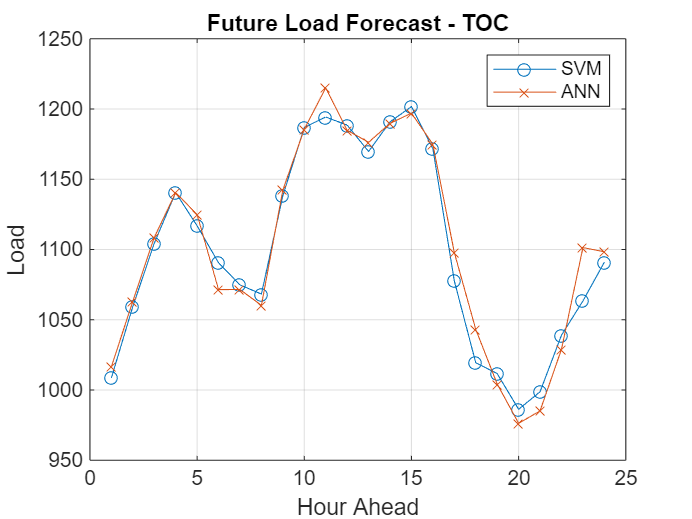

Predicting for city: san


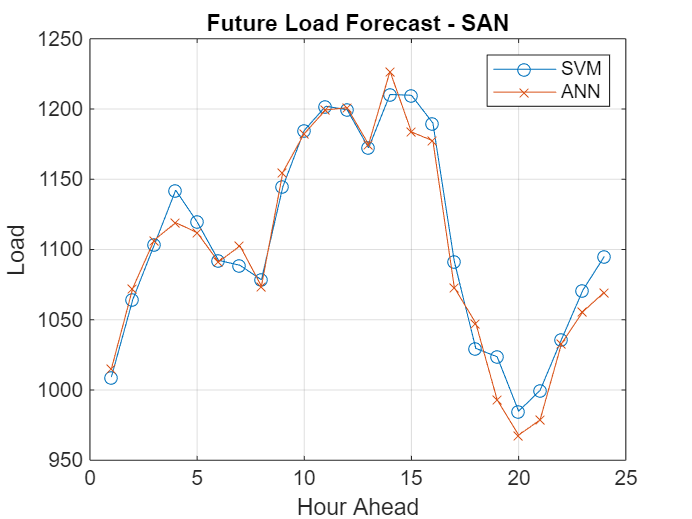

Predicting for city: dav


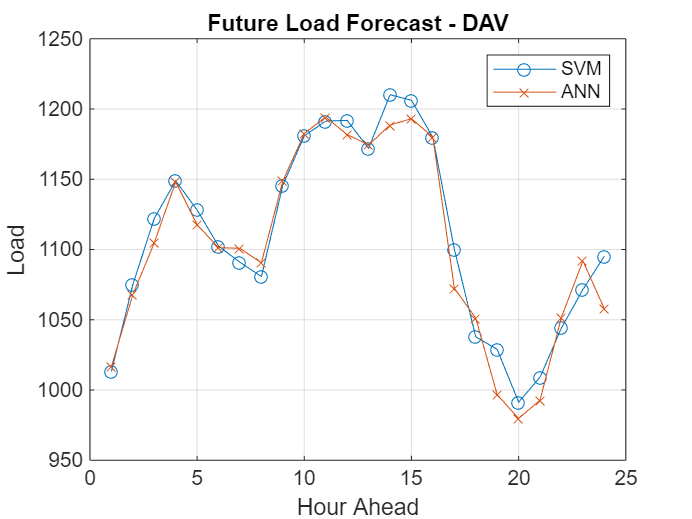

clear; clc;


data = readtable('C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\continuous dataset.csv');


cities = {'toc', 'san', 'dav'};
city_features = {
    {'T2M_toc', 'QV2M_toc', 'W2M_toc', 'TQL_toc'},
    {'T2M_san', 'QV2M_san', 'W2M_san', 'TQL_san'},
    {'T2M_dav', 'QV2M_dav', 'W2M_dav', 'TQL_dav'}
};

model_folder = 'C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\city_model_saves\';
num_lags = 24;
future_steps = 24; % Predict next 24 hours


for c = 1:length(cities)
    city = cities{c};
    features = city_features{c};
    fprintf('Predicting for city: %s\n', city);

    % Load models
    load(fullfile(model_folder, [city '_svm_model.mat']), 'svm_model', 'mu_X', 'sigma_X', 'mu_y', 'sigma_y');
    load(fullfile(model_folder, [city '_ann_model.mat']), 'ann_net');

    % Prepare data
    X = table2array(data(:, features));
    y = data.nat_demand;  

    % Create lag features
    X_lagged = [];
    for i = 1:num_lags
        X_lagged = [X_lagged, circshift(y, i)];
    end

    X = X(num_lags+1:end, :);
    X_lagged = X_lagged(num_lags+1:end, :);
    y = y(num_lags+1:end);
    X = [X, X_lagged];

    % Get latest input
    X_last = X(end, :);
    X_scaled = (X_last - mu_X) ./ sigma_X;

    % Forecast storage
    forecast_svm = zeros(future_steps, 1);
    forecast_ann = zeros(future_steps, 1);
    input_svm = X_scaled;
    input_ann = X_scaled;

    % Recursive Forecasting
    for i = 1:future_steps
        % SVM
        pred_scaled_svm = predict(svm_model, input_svm);
        pred_svm = pred_scaled_svm * sigma_y + mu_y;
        forecast_svm(i) = pred_svm;

        % ANN
        pred_scaled_ann = ann_net(input_ann');
        pred_ann = pred_scaled_ann' * sigma_y + mu_y;
        forecast_ann(i) = pred_ann;

        % Update input for next step
        input_svm(end-num_lags+1:end-1) = input_svm(end-num_lags+2:end);
        input_svm(end) = (pred_svm - mu_y) / sigma_y;

        input_ann(end-num_lags+1:end-1) = input_ann(end-num_lags+2:end);
        input_ann(end) = (pred_ann - mu_y) / sigma_y;
    end

    % Plot
    figure;
    plot(1:future_steps, forecast_svm, '-o', 'DisplayName', 'SVM');
    hold on;
    plot(1:future_steps, forecast_ann, '-x', 'DisplayName', 'ANN');
    title(['Future Load Forecast - ', upper(city)]);
    xlabel('Hour Ahead'); ylabel('Load');
    legend show; grid on;
end

clear; clc; close all;

cities = {'toc', 'san', 'dav'};
model_folder = 'C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\city_model_saves\';
data = readtable('C:\Users\yash2\OneDrive\Desktop\codes\EEE&UID\continuous dataset.csv');

% Loop through each city
future_steps = 24;
for c = 1:length(cities)
    city = cities{c};
    features = { ...
        ['T2M_' city], ['QV2M_' city], ['W2M_' city], ['TQL_' city] ...
    };

    % Load model
    svm_model_path = fullfile(model_folder, [city '_svm_model.mat']);
    ann_model_path = fullfile(model_folder, [city '_ann_model.mat']);
    load(svm_model_path, 'svm_model', 'mu_X', 'sigma_X', 'mu_y', 'sigma_y');
    load(ann_model_path, 'ann_net');

    % Prepare input data
    X_city = table2array(data(:, features));
    y_city = data.nat_demand;  
    num_lags = 24;

    % Create lagged input
    X_lagged = [];
    for i = 1:num_lags
        X_lagged = [X_lagged, circshift(y_city, i)];
    end
    X_lagged = X_lagged(num_lags+1:end, :);
    X_city = X_city(num_lags+1:end, :);
    y_city = y_city(num_lags+1:end);
    X_full = [X_city, X_lagged];

    % Get last known input
    X_last = X_full(end, :);
    X_scaled = (X_last - mu_X) ./ sigma_X;

    % Prepare for predictions
    future_pred_svm = zeros(future_steps, 1);
    future_pred_ann = zeros(future_steps, 1);
    input_svm = X_scaled;
    input_ann = X_scaled;

    fprintf('\n--- Future Load Prediction for City: %s ---\n', upper(city));
    fprintf('%5s | %10s | %10s\n', 'Hour', 'SVM (kW)', 'ANN (kW)');
    fprintf('------------------------------\n');

    for i = 1:future_steps
        % --- SVM Prediction ---
        y_pred_svm_scaled = predict(svm_model, input_svm);
        y_pred_svm = y_pred_svm_scaled * sigma_y + mu_y;
        future_pred_svm(i) = y_pred_svm;

        % --- ANN Prediction ---
        y_pred_ann_scaled = ann_net(input_ann');
        y_pred_ann = y_pred_ann_scaled' * sigma_y + mu_y;
        future_pred_ann(i) = y_pred_ann;

        % --- Display Results ---
        fprintf('%5d | %10.2f | %10.2f\n', i, y_pred_svm, y_pred_ann);

        % Update input with new prediction (scaled)
        input_svm(end-num_lags+1:end-1) = input_svm(end-num_lags+2:end);
        input_svm(end) = (y_pred_svm - mu_y) / sigma_y;

        input_ann(end-num_lags+1:end-1) = input_ann(end-num_lags+2:end);
        input_ann(end) = (y_pred_ann - mu_y) / sigma_y;
    end
end


--- Future Load Prediction for City: TOC ---


 Hour |   SVM (kW) |   ANN (kW)


------------------------------


    1 |    1008.56 |    1016.53
    2 |    1059.42 |    1063.15
    3 |    1104.45 |    1108.59
    4 |    1140.51 |    1140.43
    5 |    1116.87 |    1124.91
    6 |    1090.54 |    1071.46
    7 |    1074.80 |    1071.53
    8 |    1068.28 |    1060.24
    9 |    1138.25 |    1142.39
   10 |    1186.93 |    1185.63
   11 |    1194.30 |    1215.04
   12 |    1188.54 |    1184.87
   13 |    1169.76 |    1176.32
   14 |    1190.88 |    1189.80
   15 |    1201.76 |    1197.07
   16 |    1171.68 |    1174.89
   17 |    1077.62 |    1097.81
   18 |    1019.36 |    1043.16
   19 |    1011.67 |    1004.25
   20 |     986.26 |     976.28
   21 |     998.76 |     985.13
   22 |    1039.05 |    1029.01
   23 |    1063.39 |    1101.34
   24 |    1091.01 |    1098.39



--- Future Load Prediction for City: SAN ---


 Hour |   SVM (kW) |   ANN (kW)


------------------------------


    1 |    1009.22 |    1014.99
    2 |    1064.41 |    1072.57
    3 |    1103.24 |    1106.74
    4 |    1142.23 |    1119.10
    5 |    1119.65 |    1112.02
    6 |    1092.26 |    1091.12
    7 |    1088.76 |    1102.61
    8 |    1078.46 |    1073.89
    9 |    1144.72 |    1155.01
   10 |    1184.81 |    1182.60
   11 |    1202.01 |    1199.35
   12 |    1199.45 |    1200.95
   13 |    1172.33 |    1174.84
   14 |    1210.34 |    1226.84
   15 |    1209.80 |    1183.65
   16 |    1190.00 |    1177.38
   17 |    1091.45 |    1072.89
   18 |    1029.63 |    1047.66
   19 |    1023.62 |     992.95
   20 |     984.94 |     967.92
   21 |     999.69 |     978.67
   22 |    1035.99 |    1033.00
   23 |    1071.16 |    1055.74
   24 |    1095.10 |    1069.63



--- Future Load Prediction for City: DAV ---


 Hour |   SVM (kW) |   ANN (kW)


------------------------------


    1 |    1013.11 |    1016.51
    2 |    1074.97 |    1067.86
    3 |    1122.11 |    1104.72
    4 |    1148.92 |    1148.12
    5 |    1128.12 |    1117.62
    6 |    1102.46 |    1101.31
    7 |    1090.90 |    1100.85
    8 |    1080.72 |    1090.53
    9 |    1145.78 |    1148.83
   10 |    1180.90 |    1182.61
   11 |    1191.42 |    1194.31
   12 |    1191.88 |    1181.76
   13 |    1172.03 |    1174.47
   14 |    1210.17 |    1188.58
   15 |    1206.24 |    1193.13
   16 |    1179.82 |    1180.00
   17 |    1100.30 |    1072.50
   18 |    1037.82 |    1051.17
   19 |    1028.92 |     996.67
   20 |     991.34 |     979.69
   21 |    1009.13 |     992.83
   22 |    1044.23 |    1051.90
   23 |    1071.54 |    1091.89
   24 |    1095.37 |    1057.73
